clear

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% CARICAMENTO PARAMETRI E PREMESSE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; clc; close all;

% 1) Carica parametri di sistema
load_parameters;
%  - Questo file deve essere disponibile nello stesso path.
%  - Definisce params.m, params.b_s, params.z_eq, params.g, params.b_m, params.d, params.i_max, ecc.

% 2) Definizione di un passo di tempo e finestra di simulazione comune
dt  = 0.01;       % passo di integrazione (10 ms)
tf  = 300.0;       % tempo di simulazione di base (può cambiare a seconda degli assignment)
tSpan = linspace(0, tf, round(tf/dt));
num_steps = length(tSpan);

% 3) Funzione ODE, prototipo:
%    magnet_levitation_ode(z, z_dot, input_current, params)
% Restituisce dxdt = [z_dot; accelerazione]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% ASSIGNMENT 1: OPEN-LOOP E STABILITA' DELL'EQUILIBRIO
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Obiettivo:
%  - Mostrare con dei plot che un certo punto di equilibrio (z_eq) è asintoticamente stabile
%    quando partiamo con z(0) = z_eq + offset e z_dot(0)=0, SENZA CONTROLLO (u=0).
%  - Trovare per quali offset il sistema converge all'equilibrio.

disp('=== ASSIGNMENT 1: OPEN-LOOP ===');

=== ASSIGNMENT 1: OPEN-LOOP ===


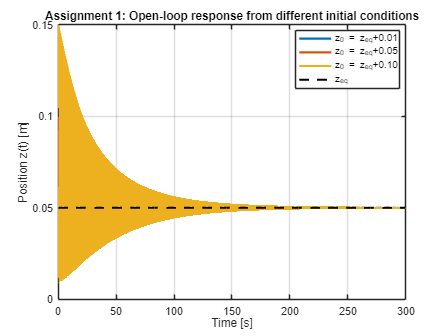


% Scelta di alcuni offset iniziali
offsets = [0.01,0.05,0.1]; 
z_eq    = params.z_eq;               % Equilibrio caricato dai parametri

% Preallocazione per salvataggi
openloop_results = cell(length(offsets), 1);

for idx = 1:length(offsets)
% Inizializzo
t_current = 0;
x_current = [z_eq + offsets(idx); 0];   % [posizione, velocità]

t_data = zeros(num_steps,1);
x_data = zeros(num_steps,2);

for i = 1:num_steps
    t_data(i)   = t_current;
    x_data(i,:) = x_current;
    
    % In open‐loop, u = 0
    u = 0;
    
    % Integro con ode15s sul piccolo intervallo [t_current, t_current+dt]
    [tout, xout] = ode15s(@(t,x) magnet_levitation_ode(x(1), x(2), u, params), ...
                          [t_current, t_current + dt], ...
                          x_current);
    x_current = xout(end,:);
    t_current = tout(end);
end

% Salvo i risultati
openloop_results{idx}.t    = t_data;
openloop_results{idx}.x    = x_data;
openloop_results{idx}.offs = offsets(idx);

end

% Plot dei risultati open‐loop
figure; hold on; grid on; box on;
colors = lines(length(offsets));
for idx = 1:length(offsets)
plot(openloop_results{idx}.t, openloop_results{idx}.x(:,1), ...
'Color', colors(idx,:), 'LineWidth',2, ...
'DisplayName', sprintf('z_{0} = z_{eq}+%.2f', offsets(idx)));
end
plot(tSpan, z_eq*ones(num_steps,1), 'k--','LineWidth',2,'DisplayName','z_{eq}');
xlabel('Time [s]'); ylabel('Position z(t) [m]');
title('Assignment 1: Open-loop response from different initial conditions');
legend('Location','Best');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% ASSIGNMENT 2: PROGETTO DI UN CONTROLLER P (ROOT LOCUS-BASED)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Obiettivo:
%  - Trovare un guadagno P che estenda la basin of stability e/o riduca il tempo di assestamento.
%  - Richiesta: settling time < 1 s per uno step su z_ref di +0.02 m.
%  - Se trovi che non esiste un P che soddisfi il requisito, spiega le ragioni.

disp('=== ASSIGNMENT 2: P-CONTROLLER ===');

=== ASSIGNMENT 2: P-CONTROLLER ===


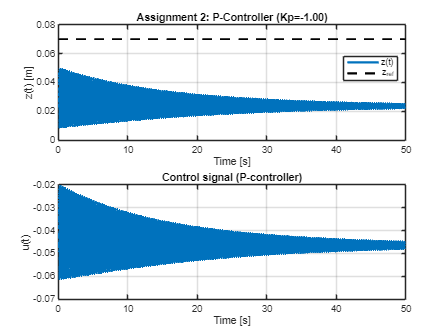


% Parametri di base
Kp = -1;  

% Configura simulazione
tf2 = 50.0;                         % tempo di simulazione
tSpan2 = linspace(0, tf2, round(tf2/dt));
num_steps2 = length(tSpan2);

% Equilibrio iniziale e step su z_ref
z_ref0   = params.z_eq;            % equilibrio di partenza
z_refEnd = z_ref0 + 0.02;          % step di ampiezza 0.02
x_current = [z_ref0; 0];           % partiamo in equilibrio (posizione = z_eq, velocità = 0)
t_current = 0;

t_dataP = zeros(num_steps2,1);
x_dataP = zeros(num_steps2,2);
u_dataP = zeros(num_steps2,1);
err_dataP = zeros(num_steps2,1);

for i = 1:num_steps2
t_dataP(i)   = t_current;
x_dataP(i,:) = x_current;

% Reference: step(t)
% Per t>=0, z_ref = z_refEnd
z_ref = z_refEnd; 
error = z_ref - x_current(1);
err_dataP(i) = error;

% Legge di controllo: u = Kp * (z_ref - z)
u = Kp * error;
u_dataP(i) = u;

% Integro piccolo intervallo
[tout, xout] = ode15s(@(t,x) magnet_levitation_ode(x(1), x(2), u, params), ...
                      [t_current, t_current+dt], ...
                      x_current);
x_current = xout(end,:);
t_current = tout(end);

end

% Plot dei risultati (position + reference)
figure;
subplot(2,1,1); hold on; grid on; box on;
plot(t_dataP, x_dataP(:,1),'LineWidth',2);
plot(t_dataP, z_refEnd*ones(num_steps2,1),'k--','LineWidth',2);
xlabel('Time [s]'); ylabel('z(t) [m]');
title(sprintf('Assignment 2: P-Controller (Kp=%.2f)',Kp));
legend({'z(t)','z_{ref}'}, 'Location','Best');

% Plot del segnale di controllo
subplot(2,1,2); hold on; grid on; box on;
plot(t_dataP, u_dataP,'LineWidth',2);
xlabel('Time [s]'); ylabel('u(t)');
title('Control signal (P-controller)');




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% ASSIGNMENT 3: PROGETTO DI UN CONTROLLER PID
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Obiettivo:
%  - Scegli (impiricamente o con un metodo formale) Kp, Ki, Kd per
%    ottenere certe prestazioni (settling time, overshoot, stability margin).
%
%  - Esempio: useremo un PID "classico" in forma
%        u(t) = Kp * e(t) + Ki * ∫ e(t) dt + Kd * de(t)/dt

disp('=== ASSIGNMENT 3: PID CONTROLLER ===');

=== ASSIGNMENT 3: PID CONTROLLER ===


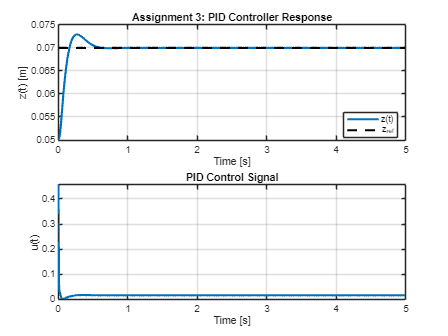


% Parametri del PID
Kp_pid = 1.8374;
Ki_pid = 15.4;
Kd_pid = 0.2083;

% Setup simulazione
tf3 = 5.0;
tSpan3 = linspace(0, tf3, round(tf3/dt));
num_steps3 = length(tSpan3);

% Step reference da z_eq a z_eq+0.02
z_ref0    = params.z_eq;
z_refStep = z_ref0 + 0.02;

x_current  = [z_ref0; 0];
t_current  = 0;
error_int  = 0;    % integratore
error_prev = 0;    % per termine derivativo

t_dataPID   = zeros(num_steps3,1);
x_dataPID   = zeros(num_steps3,2);
u_dataPID   = zeros(num_steps3,1);
err_dataPID = zeros(num_steps3,1);

for i = 1:num_steps3
t_dataPID(i)   = t_current;
x_dataPID(i,:) = x_current;

% Riferimento (step)
z_ref = z_refStep; 
error = z_ref - x_current(1);
err_dataPID(i) = error;

% Calcolo PID
error_int = error_int + error*dt;         % integrale
error_der = (error - error_prev)/dt;      % derivata (appross.)
error_prev = error;                       % aggiorno per il prossimo step

u_pid = Kp_pid*error + Ki_pid*error_int + Kd_pid*error_der;

% (Opzionale) saturazione del segnale di controllo entro ±i_max
% u_pid = max(min(u_pid, params.i_max), -params.i_max);

u_dataPID(i) = u_pid;

% Integrazione dell'ODE per un intervallo [t_current, t_current + dt]
[tout, xout] = ode15s( @(t,x) magnet_levitation_ode( x(1), x(2), u_pid, params ), ...
                       [t_current, t_current+dt], x_current );
x_current = xout(end,:);
t_current = tout(end);

end

figure;
subplot(2,1,1); hold on; grid on; box on;
plot(t_dataPID, x_dataPID(:,1),'LineWidth',2);
plot(t_dataPID, z_refStep*ones(num_steps3,1), 'k--','LineWidth',2);
xlabel('Time [s]'); ylabel('z(t) [m]');
title('Assignment 3: PID Controller Response');
legend({'z(t)','z_{ref}'}, 'Location','Best');

subplot(2,1,2); hold on; grid on; box on;
plot(t_dataPID, u_dataPID,'LineWidth',2);
xlabel('Time [s]'); ylabel('u(t)');
title('PID Control Signal');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% ASSIGNMENT 4: SPINGERE IL MAGNETE PIU' IN ALTO POSSIBILE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Obiettivo:
%  - Scegliere un controller (tra P, PID, o un altro)
%  - Mandare il riferimento verso l'alto gradualmente, vedere fino a dove si riesce
%    a stabilizzare il magnete prima che perda la stabilità.
%  - Plot di z_ref(t) e z(t), e commento su "quanto in alto" si è andati.

disp('=== ASSIGNMENT 4: PUSHING THE MAGNET HIGH ===');

=== ASSIGNMENT 4: PUSHING THE MAGNET HIGH ===


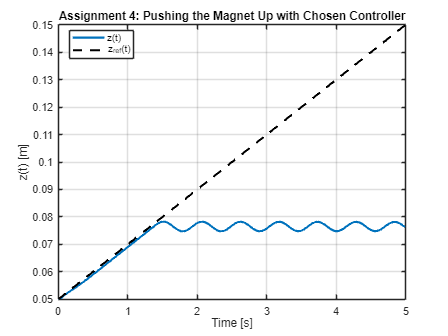


% Useremo lo stesso PID trovato prima

tf4 = 5.0;
tSpan4 = linspace(0, tf4, round(tf4/dt));
num_steps4 = length(tSpan4);

% Costruiamo un riferimento crescente (rampa)
% Partiamo da z_eq, e saliamo di 0.02 m/s per 5 secondi
ramp_rate = 0.02;  % [m/s] velocità di salita
x_current  = [params.z_eq; 0]; % stato iniziale [z(0); z_dot(0)]
t_current  = 0;
error_int  = 0;
error_prev = 0;

t_data4     = zeros(num_steps4,1);
z_data4     = zeros(num_steps4,1);
x_data4_rec = zeros(num_steps4,2);
u_data4     = zeros(num_steps4,1);

for i = 1:num_steps4
% Riferimento ramp(t) = z_eq + ramp_rate * t
z_ref = params.z_eq + ramp_rate*t_current;

% Salviamo tempo e stato
t_data4(i)     = t_current;
x_data4_rec(i,:) = x_current;
z_data4(i)     = z_ref;

% Calcolo dell'errore
error = z_ref - x_current(1);

% PID
error_int  = error_int + error*dt;
error_der  = (error - error_prev)/dt;
error_prev = error;

% Segnale di controllo
u_pid = Kp_pid * error + Ki_pid * error_int + Kd_pid * error_der;

% (Opzionale) saturazione per evitare di superare i limiti di corrente
% u_pid = max(min(u_pid, params.i_max), -params.i_max);

u_data4(i) = u_pid;

% Integrazione ODE per l'intervallo [t_current, t_current+dt]
[tout, xout] = ode15s(@(t,x) magnet_levitation_ode( x(1), x(2), u_pid, params ), ...
                      [t_current, t_current + dt], ...
                      x_current);
x_current  = xout(end,:);
t_current  = tout(end);

end

% Plot
figure; hold on; grid on; box on;
plot(t_data4, x_data4_rec(:,1), 'LineWidth',2, 'DisplayName','z(t)');
plot(t_data4, z_data4, 'k--','LineWidth',2, 'DisplayName','z_{ref}(t)');
xlabel('Time [s]');
ylabel('z(t) [m]');
title('Assignment 4: Pushing the Magnet Up with Chosen Controller');
legend('Location','Best');
legend('Location','Best');

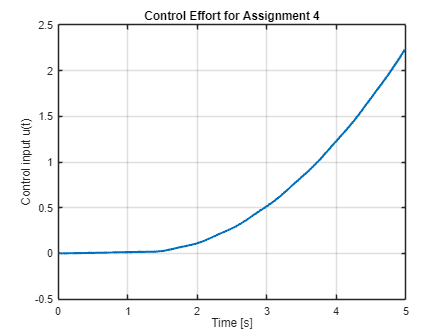

% il segnale di controllo:
figure; hold on; grid on; box on;
plot(t_data4, u_data4, 'LineWidth',2);
xlabel('Time [s]');
ylabel('Control input u(t)');
title('Control Effort for Assignment 4');



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% ASSIGNMENT 5: TRACKING SINE E SQUARE WAVE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Obiettivo:
%  - Usare un controller (P, PID, o a scelta) e verificare la tracking performance
%    su due tipi di riferimento:
%      1) z_ref(t) = z0 + 0.01 sin(2πt)
%      2) z_ref(t) = z0 + 0.01 squarewave(2πt) (es. sign(sin(2πt))?)
%
%  - Verificare se l'errore rimane < 2mm in ogni istante.

disp('=== ASSIGNMENT 5: TRACKING SINE AND SQUARE WAVE ===');

=== ASSIGNMENT 5: TRACKING SINE AND SQUARE WAVE ===


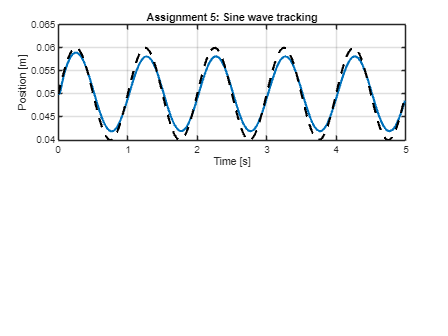

Unrecognized function or variable 'D'.


tf5 = 5.0;
tSpan5 = linspace(0, tf5, round(tf5/dt));
num_steps5 = length(tSpan5);

% Parametri comune
x_current = [params.z_eq; 0];   % partiamo da z_eq
t_current = 0;
error_int = 0;
error_prev = 0;

z0 = params.z_eq;
ampl = 0.01;   % ampiezza dell'oscillazione

% Prealloco
t_data5   = zeros(num_steps5,1);
z_data5   = zeros(num_steps5,1);
x_data5   = zeros(num_steps5,2);
u_data5   = zeros(num_steps5,1);
err_data5 = zeros(num_steps5,1);

% due simulazioni separate: prima la sinusoide e poi la square

%%%%%%%% TRACKING DI UNA SINUSOIDE %%%%%%%%%
for i = 1:num_steps5
t_data5(i)   = t_current;
x_data5(i,:) = x_current;

% Riferimento sinusoidale: z_ref = z0 + ampl*sin(2π t)
z_ref = z0 + ampl*sin(2*pi*t_current);
z_data5(i) = z_ref;

error = z_ref - x_current(1);
err_data5(i) = error;

% PID
error_int = error_int + error*dt;
error_der = (error - error_prev)/dt;
error_prev = error;

u_pid = Kp_pid*error + Ki_pid*error_int + Kd_pid*error_der;
u_data5(i) = u_pid;

[tout, xout] = ode15s(@(t,x) magnet_levitation_ode(x(1), x(2), u_pid, params), ...
                      [t_current, t_current+dt], ...
                      x_current);
x_current = xout(end,:);
t_current = tout(end);

end

% Plot sinusoid
figure;
subplot(2,1,1); hold on; grid on; box on;
plot(t_data5, x_data5(:,1),'LineWidth',2,'DisplayName','z(t)');
plot(t_data5, z_data5, 'k--','LineWidth',2,'DisplayName','z_{ref}(t)');
xlabel('Time [s]'); ylabel('Position [m]');
title('Assignment 5: Sine wave tracking');D

legend('Location','Best');

subplot(2,1,2); hold on; grid on; box on;
plot(t_data5, err_data5, 'LineWidth',2);
xlabel('Time [s]'); ylabel('Error [m]');
title('Tracking Error (Sine)');


%%%%%%%% TRACKING DI UNA SQUARE WAVE %%%%%%%%%
% Re-inizializzo l'integratore e lo stato
x_current = [params.z_eq; 0];
t_current = 0;
error_int = 0;
error_prev = 0;
t_data5_sq   = zeros(num_steps5,1);
z_data5_sq   = zeros(num_steps5,1);
x_data5_sq   = zeros(num_steps5,2);
err_data5_sq = zeros(num_steps5,1);

for i = 1:num_steps5
t_data5_sq(i)   = t_current;
x_data5_sq(i,:) = x_current;

% squarewave(2πt): possiamo usare sign(sin(2πt)).
% Se preferisci un'onda quadra “morbida”, puoi usare "square(2πt)" di MATLAB Signal Toolbox.
% Riferimento = z0 + ampl * sign(sin(2π t))
sq_val = sign(sin(2*pi*t_current));   % assume +1/-1
z_ref = z0 + ampl * sq_val;
z_data5_sq(i) = z_ref;

error = z_ref - x_current(1);
err_data5_sq(i) = error;

% stesse eq. PID
error_int = error_int + error*dt;
error_der = (error - error_prev)/dt;
error_prev = error;

u_pid = Kp_pid*error + Ki_pid*error_int + Kd_pid*error_der;

[tout, xout] = ode15s(@(t,x) magnet_levitation_ode(x(1), x(2), u_pid, params), ...
                      [t_current, t_current+dt], ...
                      x_current);
x_current = xout(end,:);
t_current = tout(end);

end

% Plot square wave tracking
figure;
subplot(2,1,1); hold on; grid on; box on;
plot(t_data5_sq, x_data5_sq(:,1), 'LineWidth',2, 'DisplayName','z(t)');
plot(t_data5_sq, z_data5_sq, 'k--','LineWidth',2, 'DisplayName','z_{ref}(t)');
xlabel('Time [s]'); ylabel('Position [m]');
title('Assignment 5: Square wave tracking');
legend('Location','Best');

subplot(2,1,2); hold on; grid on; box on;
plot(t_data5_sq, err_data5_sq, 'LineWidth',2);
xlabel('Time [s]'); ylabel('Error [m]');
title('Tracking Error (Square Wave)');

disp('=== FINE DELLA SIMULAZIONE UNIFICATA ===');